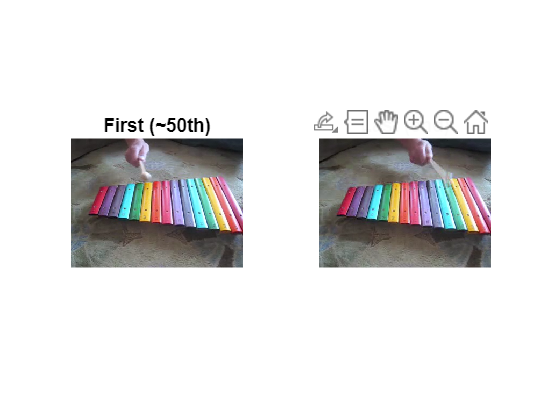

p = which('xylophone.mp4');
v = VideoReader(p);
v.CurrentTime = (50-1)/v.FrameRate;
A = {};
while hasFrame(v)
    A{end+1} = readFrame(v);
end
if ~isempty(A)
    figure; tiledlayout(1,2); nexttile; imshow(A{1}); title('First (~50th)'); nexttile; imshow(A{end}); title('Last (end)');
end

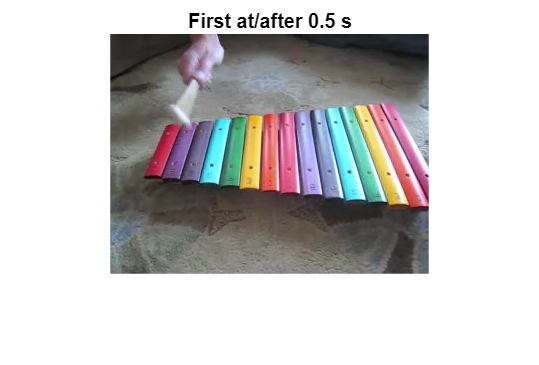

v.CurrentTime = 0.5;
B = {};
while hasFrame(v)
    B{end+1} = readFrame(v);
end
if ~isempty(B)
    figure; imshow(B{1}); title('First at/after 0.5 s');
end

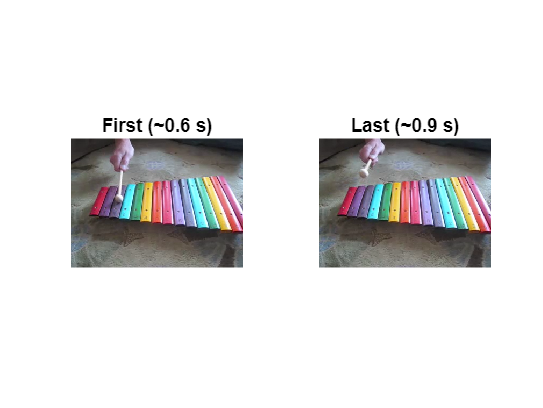

v.CurrentTime = 0.6;
C = {};
while hasFrame(v) && v.CurrentTime < 0.9
    C{end+1} = readFrame(v);
end
if ~isempty(C)
    figure; tiledlayout(1,2); nexttile; imshow(C{1}); title('First (~0.6 s)'); nexttile; imshow(C{end}); title('Last (~0.9 s)');
end